# Opgave 1: Gram-Schmidt

#### Oefening 3

m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.0591   -0.1070   -0.0690   -0.0563   -0.0582   -0.0577   -0.0593   -0.0608   -0.0588   -0.0591   -0.0591   -0.0590   -0.0591   -0.0590   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591   -0.0591
    0.0150   -0.0160    0.0097    0.0181    0.0162    0.0133    0.0164    0.0151    0.0151    0.0150    0.0150    0.0149    0.0150    0.0149    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0.0150    0

#### Oefening 4

e1 = zeros(n, 1);
e2 = zeros(n, 1);

[Q1,~] = klGS(A)

Q1 =    -0.0591   -0.0959   -0.0398    0.0220    0.0130    0.0426   -0.0144   -0.2259    0.0616   -0.0105    0.0006    0.0756    0.0039    0.0741    0.0202    0.0050   -0.0212   -0.0159   -0.0840    0.0696    0.0345    0.0495   -0.0285   -0.0753   -0.1218    0.0284    0.1129    0.0849    0.0885    0.0874    0.0856    0.0853    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851    0.0851
    0.0150   -0.0620   -0.0212    0.0248    0.0191   -0.0546    0.0892    0.0228    0.0305    0.0103    0.0381   -0.0287    0.0127   -0.1038    0.1167    0.0197   -0.0295   -0.1473    0.0086    0.0250   -0.0785   -0.0592   -0.0195   -0.0612   -0.1104    0.0276   -0.0374   -0.0427   -0.0395   -0.0455   -0.0441   -0.0437   -0.0438   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -0.0437   -

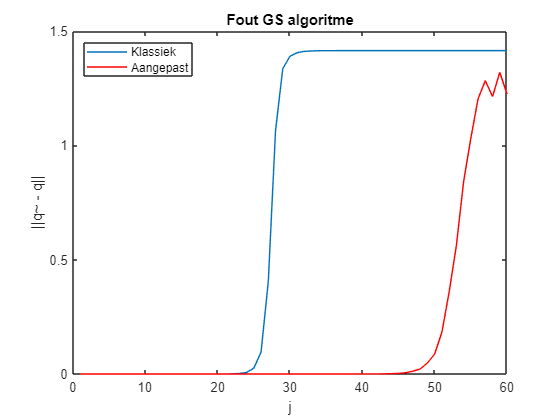

[Q2,~] = modGS(A);

for j = 1:n
    e1(j, 1) = norm(Q1(:,j)-Q(:,j));
    e2(j, 1) = norm(Q2(:,j)-Q(:,j));
end

% linear scale plot
plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest')

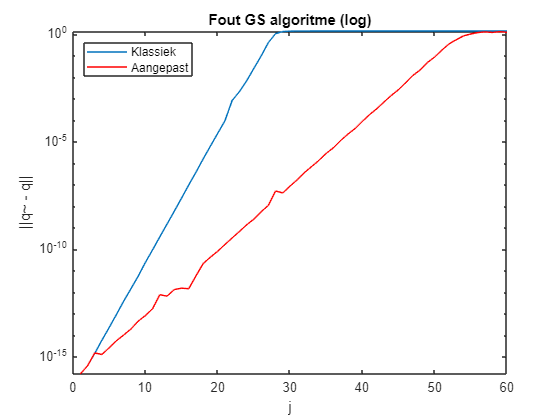


% logarithmic scale plot
plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme (log)")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest')
set(gca, 'YScale', 'log')

#### Oefening 8

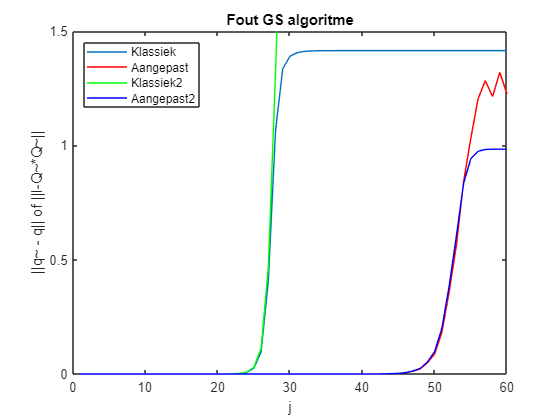

orth1 = zeros(n, 1);
orth2 = zeros(n, 1);

for j = 1:n
    orth1(j, 1) = norm(eye(j) - Q1(:,1:j)'*Q1(:,1:j));
    orth2(j, 1) = norm(eye(j) - Q2(:,1:j)'*Q2(:,1:j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold on
plot(orth1, 'Color', 'g')
hold on
plot(orth2,'Color','b')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q|| of ||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Klassiek2', 'Aangepast2', 'Location','northwest')
axis([0 60 0 1.5])

#### Oefening 5

m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.0042   -0.0057    0.0113
    0.0651    0.0022    0.0443
    0.0060   -0.0142    0.0036
    0.0352    0.0081    0.0507
    0.0455    0.0936    0.0604
    0.0354    0.0724    0.0449
    0.0327    0.0001    0.0629
    0.0667    0.0311    0.0763
   -0.0043    0.0451   -0.0090
    0.0491   -0.0074    0.0575


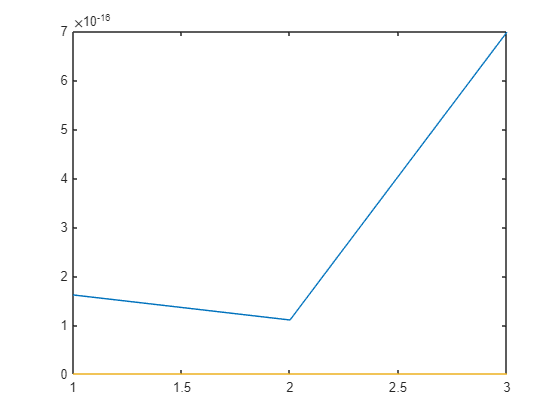


e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)

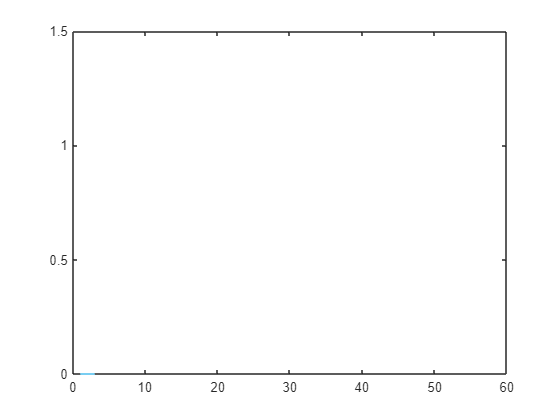


% comparison of theoretical error (te) with experimental error (e)
te1 = zeros(n);
te2 = zeros(n);
x = zeros(1,n);
for j = 1:n
    x(j) = 2^(j-1);
    te1(j) = 2^(j-1)*norm(x)*eps;
    te2(j) = 2^(j-1)*eps;
end
plot(te1)
hold on
plot(te2)
hold off
axis([0 60 0 1.5])

#### Oefening 9

m = 200;
n = 50;
k = 1:50;

B = randn(m,n);
[Q,~] = qr(B,0);

[V,~] = qr(rand(n));
V = 10*rand*V;

D = zeros(n);
for i = k
    D(:,:,i) = diag(2.^linspace(0,i,n));
end
D;

A = zeros(m, n);
for i = k
    A(:,:,i) = Q*D(:,:,i)*V;
end
A;

A = A(:,:,1) =

   -1.2925    0.2707   -0.8080    1.5920   -0.2567    0.2211    0.1324    0.7027    0.1777    0.3364    0.3475    0.1010   -0.3520   -0.4318    0.2468   -0.6030    0.3746   -1.4177    0.0417    0.0489    1.0062   -0.5013   -0.0416    0.5629    1.2190    0.3073    0.3869   -0.0567    0.1952    0.7369   -0.5567   -0.8653    0.1047    0.2212    0.2172    0.0785    0.1961   -0.2010   -0.4562   -0.3236   -0.1130    0.1567    0.4032   -0.5949   -0.7469    1.3153    0.8081   -0.2982    0.1542    0.3630
   -0.3810   -0.2339    0.8528    0.4042   -0.5723    0.6266   -0.1329    0.2340    0.2549    1.0864   -0.5925   -0.7362    1.8460   -0.5854    0.5635    0.0426    0.3011    0.2092   -0.0708    0.1462   -0.4651    0.3377    1.2276   -0.0154   -0.6282    0.6052    0.1671    0.6086    0.3101   -0.4762    0.6371   -0.3653   -0.1047   -0.0673    0.6753   -0.2256   -0.0069    0.4590    0.4074    0.2768    0.3612   -1.2123   -0.2922    0.2302   -0.6641   -0.6673    0.5474   -0.3328   


K = zeros(length(k), 1);
for i = k
    K(i) = norm(A(:,:,i)) * norm(pinv(A(:,:,i)));
end
K

K = 1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


#### Oefening 10

Q1 = zeros(m, n);
for i = k
    [Q1(:,:,i),~] = klGS(A(:,:,i));
end
Q1;

Q2 = zeros(m, n);
for i = k
    [Q2(:,:,i),~] = modGS(A(:,:,i));
end
Q2;

Q3 = zeros(m, n);
for i = k
    [Q3(:,:,i),~] = herGS(A(:,:,i));
end
Q3;

orth1 = zeros(length(k), 1);
for i = k
    orth1(i) = norm(eye(n) - Q1(:,:,i)'*Q1(:,:,i));
end
orth1;

orth2 = zeros(length(k), 1);
for i = k
    orth2(i) = norm(eye(n) - Q2(:,:,i)'*Q2(:,:,i));
end
orth2;

orth3 = zeros(length(k), 1);
for i = k
    orth3(i) = norm(eye(n) - Q3(:,:,i)'*Q3(:,:,i));
end
orth3;

plot(k, orth1, 'b', k, orth2, 'r', k, orth3, 'g')
hold off
title("Fout GS algoritme")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Herhaald', 'Location','northwest')

# Opgave 2: Iteratieve methoden

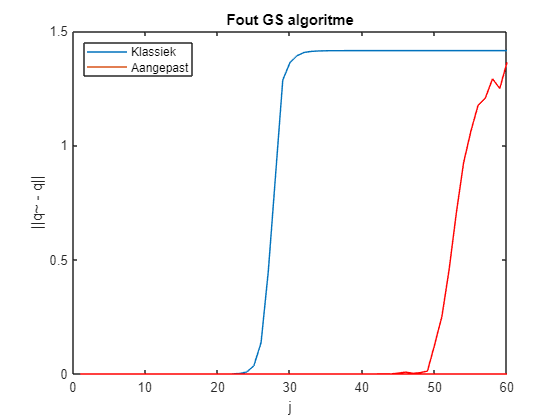

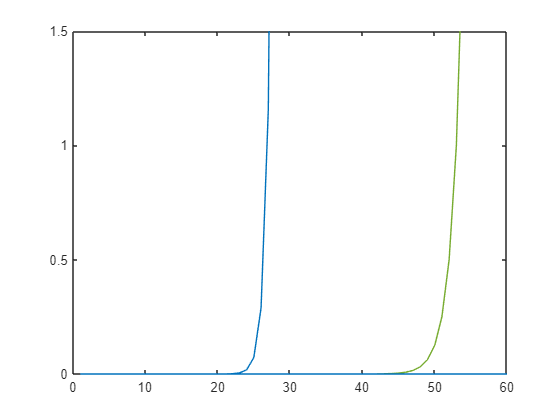

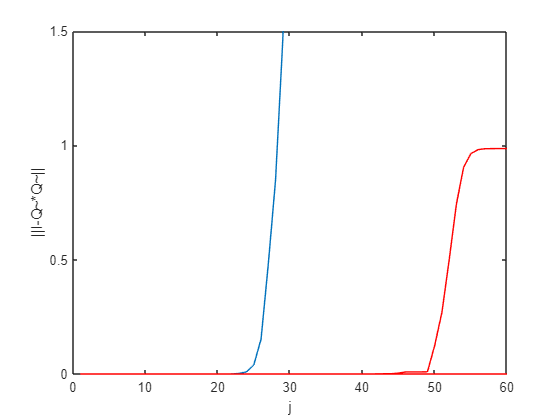

A = A(:,:,1) =

   -0.5579    1.7720    0.7738    0.6625    1.7215   -0.1061   -1.1897   -2.1412   -0.3272    0.6328    0.4029    0.2931   -0.0774   -0.5048   -0.3004    0.5542   -1.0118   -0.2620   -0.3044   -0.6741   -0.6090   -0.2062    0.4515    0.6068   -0.9714    0.4787   -1.2948   -0.1638   -0.0572    0.7356   -0.7467   -0.6498   -0.8357   -0.5101   -0.9322   -0.7809    0.1696    0.3975   -0.7675    0.6913   -0.1712   -0.2303    0.5470    0.2005    0.5055   -0.2639   -0.6732   -0.1983   -0.7709   -0.8037
   -1.9988    0.9850   -1.4600   -0.4843   -1.8045   -0.5825   -0.6745    0.1310    0.5897    0.7412   -1.0316   -0.7241    0.4841   -0.6823    0.2840   -0.1230   -0.6698    0.5683    0.8760   -0.9113   -0.1438    0.0341    1.7092    0.6994    0.0338    0.5627    0.6192    0.8402    0.7045    0.0732   -1.5494    1.0468   -0.4330   -0.1900    0.5031    1.0966    0.3942    1.2652   -1.4499    0.1086    0.6137    0.2745    1.0220   -0.8750   -0.2433   -1.1459   -0.9563   -0.1581   

K = 1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Q1 = Q1(:,:,1) =

   -0.0595    0.1774    0.1032    0.0881    0.1506   -0.0353   -0.1408   -0.1943   -0.0508    0.0124   -0.0313    0.0560   -0.0312   -0.0125   -0.0825    0.0023   -0.0998   -0.0535    0.1121    0.0501   -0.1287    0.0144    0.1249   -0.0045    0.0001    0.0556   -0.0144    0.0213   -0.0192    0.0236   -0.0310    0.0510   -0.0917    0.0806   -0.0957   -0.0223   -0.0148   -0.0101    0.0206   -0.0225   -0.1581   -0.0450   -0.0419    0.0279   -0.0318   -0.0434    0.0326    0.0334    0.1079    0.0782
   -0.2132    0.0910   -0.1142   -0.0472   -0.1093   -0.0743   -0.1165   -0.0130    0.0243   -0.0670   -0.0621    0.0010    0.0652   -0.0583   -0.0423    0.0224   -0.0177    0.0686    0.1385   -0.0176   -0.0083    0.0986    0.0460    0.0544    0.1061   -0.0455    0.0296   -0.0444    0.1342    0.0034   -0.0340    0.0463   -0.1769    0.0435   -0.0106    0.0606   -0.0292    0.1653   -0.1006    0.1341   -0.0034    0.0421   -0.0496   -0.0365   -0.1119   -0.0762   -0.0101   -0.1045 

Q2 = Q2(:,:,1) =

   -0.0595    0.1774    0.1032    0.0881    0.1506   -0.0353   -0.1408   -0.1943   -0.0508    0.0124   -0.0313    0.0560   -0.0312   -0.0125   -0.0825    0.0023   -0.0998   -0.0535    0.1121    0.0501   -0.1287    0.0144    0.1249   -0.0045    0.0001    0.0556   -0.0144    0.0213   -0.0192    0.0236   -0.0310    0.0510   -0.0917    0.0806   -0.0957   -0.0223   -0.0148   -0.0101    0.0206   -0.0225   -0.1581   -0.0450   -0.0419    0.0279   -0.0318   -0.0434    0.0326    0.0334    0.1079    0.0782
   -0.2132    0.0910   -0.1142   -0.0472   -0.1093   -0.0743   -0.1165   -0.0130    0.0243   -0.0670   -0.0621    0.0010    0.0652   -0.0583   -0.0423    0.0224   -0.0177    0.0686    0.1385   -0.0176   -0.0083    0.0986    0.0460    0.0544    0.1061   -0.0455    0.0296   -0.0444    0.1342    0.0034   -0.0340    0.0463   -0.1769    0.0435   -0.0106    0.0606   -0.0292    0.1653   -0.1006    0.1341   -0.0034    0.0421   -0.0496   -0.0365   -0.1119   -0.0762   -0.0101   -0.1045 

Q3 = Q3(:,:,1) =

   -0.0595    0.1747    0.1359    0.0802    0.1657   -0.0691   -0.1098   -0.1253   -0.0668   -0.0374   -0.1185    0.1286   -0.0322   -0.0009   -0.1636   -0.0613   -0.0850   -0.0878    0.1424    0.0900   -0.0755    0.0612    0.1818   -0.1099    0.0893    0.0086    0.1383   -0.1784   -0.0614    0.0226    0.0885    0.0689   -0.0107    0.0148   -0.0116    0.0404    0.0574   -0.0248    0.0099   -0.0615   -0.0593   -0.0365   -0.0196    0.0444   -0.1103    0.0745    0.1264   -0.0514    0.1022    0.1542
   -0.2132    0.0819   -0.1045   -0.0200   -0.0803   -0.0616   -0.1377   -0.0406    0.0089   -0.1536    0.0011    0.0789    0.0087   -0.0018   -0.1457    0.0422   -0.0066    0.0027    0.1570    0.1274   -0.0996    0.1559    0.1024   -0.0898    0.1462   -0.0210    0.1357   -0.1249   -0.0876    0.1095    0.1398   -0.0103   -0.0994   -0.0682   -0.1172    0.0829    0.1059    0.1096   -0.0812   -0.1244    0.0866    0.0285   -0.0160    0.1226   -0.0878    0.1327    0.1434    0.0647 

orth1 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


orth2 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


orth3 =    21.7399
   30.6799
   32.6976
   36.7779
   38.7835
   37.5306
   34.6494
   32.8230
   30.4188
   28.1365


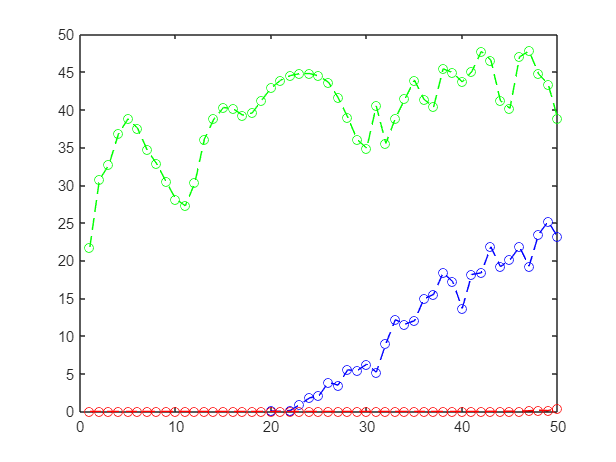

ans = 2.2204e-16

ans = 2.6752e-16

ans = 0.8300

A = sprand(1000,1000, 100);
n = length(A);
m = 100;
v = rand(n,1);

ritzvaluesiterations = zeros(m, 6);
for i=1:m
    [V,H] = Arnoldi(A,v,i);
    Hn = H(1:i, :);
    [~, ritzvalues] = eigs(Hn);
    for k=1:length(ritzvalues)
        ritzvaluesiterations(i, k) = ritzvalues(k, k);
    end
end
[V,H] = Arnoldi(A,v,m);

colors = ['g', 'b', 'c', 'r', 'm', 'y']
eigenvalues = zeros(6, 1);
[~, eigenvaluesdiagonal] = eigs(A);
for eigenvalue=1:6
    eigenvalues(eigenvalue) = eigenvaluesdiagonal(eigenvalue, eigenvalue);
    plot(real(eigenvalues(eigenvalue)), imag(eigenvalues(eigenvalue)), 'x', "MarkerSize",20, "Color", colors(eigenvalue))
    hold on
end

eigenvalues
ritzvaluesiterations;
Hn = H(1:m, :);
[~, ritzvalues] = eigs(Hn);

ritz1 = ritzvaluesiterations(:, 1)
ritz2 = ritzvaluesiterations(:, 2)
ritz3 = ritzvaluesiterations(:, 3)
ritz4 = ritzvaluesiterations(:, 4)
ritz5 = ritzvaluesiterations(:, 5)
ritz6 = ritzvaluesiterations(:, 6)
for k=1:100
    if k < 91
        plot(real(ritz1(k)), imag(ritz1(k)), '.', 'Color', 'k')
        plot(real(ritz2(k)), imag(ritz2(k)), '.', 'Color', 'k')
        plot(real(ritz3(k)), imag(ritz3(k)), '.', 'Color', 'k')
        plot(real(ritz4(k)), imag(ritz4(k)), '.', 'Color', 'k')
        plot(real(ritz5(k)), imag(ritz5(k)), '.', 'Color', 'k')
        plot(real(ritz6(k)), imag(ritz6(k)), '.', 'Color', 'k')
    end
    if k >= 91
        plot(real(ritz1(k)), imag(ritz1(k)), 'o', 'Color', colors(1))
        plot(real(ritz2(k)), imag(ritz2(k)), 'o', 'Color', colors(2))
        plot(real(ritz3(k)), imag(ritz3(k)), 'o', 'Color', colors(3))
        plot(real(ritz4(k)), imag(ritz4(k)), 'o', 'Color', colors(4))
        plot(real(ritz5(k)), imag(ritz5(k)), 'o', 'Color', colors(5))
        plot(real(ritz6(k)), imag(ritz6(k)), 'o', 'Color', colors(6))
    end
    pause(0.1)
end

hold off
title("Ritzwaarden")
xlabel('Real')
ylabel('Imaginary')